% Implementation of Hill-climbing algorithm
% for single fiber-waveguide alignment case

% as you iterate, check each possible move from current point
% and move in the direction of greatest increase

num_moves = 9;
moves = [1, 1; 
        1, -1; 
        -1, 1; 
        -1, -1;
        0, 0;
        1, 0;
        -1, 0;
        0, 1;
        0, -1];
step_size = 0.01;
moves = moves * step_size;

x_star = 0.75;
y_star = 0.5;

threshold = 1e-6;
pos_moves = [];

while 1 == 1
    next_fun_val = zeros(num_moves, 1);
    for i = 1:num_moves
        next_fun_val(i) = I(x_star+moves(i,1), y_star+moves(i, 2));
    end
    [max_val, pos] = max(next_fun_val);
    x_star_new = x_star+moves(pos,1);
    y_star_new = y_star+moves(pos,2);
    pos_moves = [pos_moves; x_star_new, y_star_new];
    if x_star_new - x_star == 0 && y_star_new - y_star == 0
        x_star = x_star_new;
        y_star = y_star_new;
        break;
    end
    x_star = x_star_new;
    y_star = y_star_new;
end
x_star

x_star = -5.3083e-16

y_star

y_star = -3.0878e-16

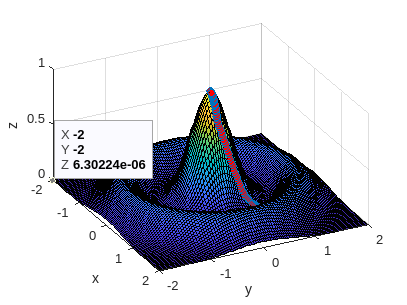


N = 2.0;
x=linspace(-N, N);
y=x;
[X,Y] = meshgrid(x,y);

scatter3(pos_moves(:,1), pos_moves(:,2), I(pos_moves(:,1),pos_moves(:,2)), 'MarkerFaceColor','red')
hold on
%view(3);
surf(X,Y,I(X,Y));
colormap("parula")
xlabel("x")
ylabel("y")
zlabel("z")

%axis equal square;



function intensity = I(x, y)
intensity = exp(-4.*(x.^2 + y.^2)) + ...
    0.25*exp(-6.*((x.^2+y.^2).^(1/2)-1.5).^2);
end